# SESION 7 DE LABORATORIO

# PRACTICA 16

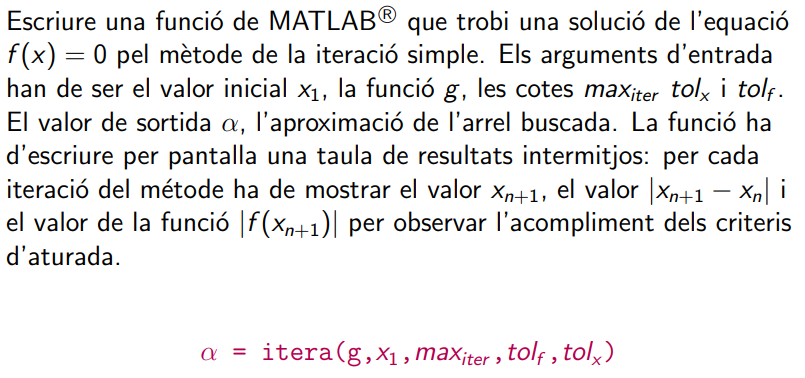

## Test

clear,clc,format long

f=@(x)x.*exp(x)-1;
zero=fzero(f,0.5)

zero =    0.567143290409784


g=@(x)exp(-x);
x0 = 0.5;
tol = 1e-5;
maxiter = 100;

alpha = itera(g,x0,maxiter,tol,tol,true)

ans = 18×4 table
    it         x_next                tolx_aux                tolf_aux      
    __    _________________    ____________________    ____________________

     1    0.606530659712633       0.106530659712633      0.0612914478200284
     2    0.545239211892605      0.0612914478200284      0.0344638829854632
     3    0.579703094878068      0.0344638829854632      0.0196384669391664
     4    0.560064627938902      0.0196384669391664      0.0111075210383133
     5    0.571172148977215      0.0111075210383133     0.00630920199689167
     6    0.564862946980323     0.00630920199689167     0.00357510058974275
     7    0.568438047570066     0.00357510058974275     0.00202859482314544
     8    0.566409452746921     0.00202859482314544     0.00115018151532165
     9    0.567559634262242     0.00115018151532165    0.000652421326771013
    10    

alpha =    0.567147746330625


# PRACTICA 17

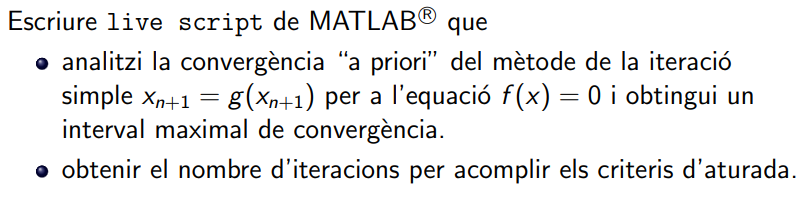

clear,clc,format long

f=@(x)x.*exp(x)-1;
g=@(x)exp(-x);
dg=@(x)-exp(-x);


Primero realizamos un** estudio grafico** para localizar la zona de interes:

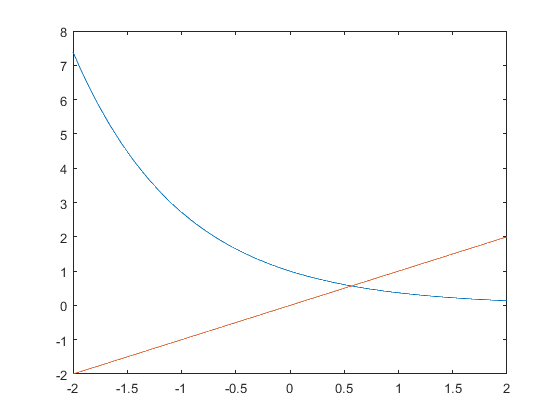

x = [-2:0.01:2];
plot(x,g(x), x, x);

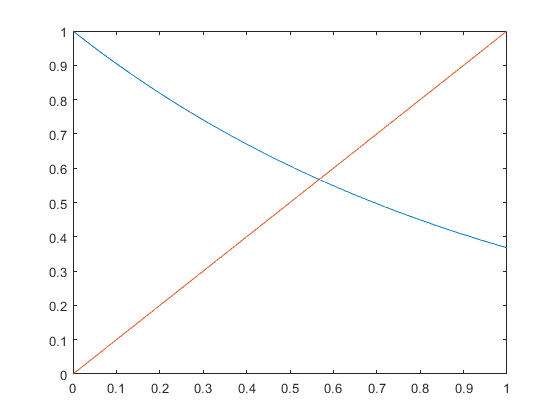

x = [0:0.01:1];
plot(x,g(x), x, x);

Podemos ver como **entre 0.5 y 0.6 se encuentra el punto de corte**. Escogemos **x0 = 0.5**.

x0 = 0.5;

if (abs(dg(x0))) < 1
    disp("A priori convergente");
else
    disp("A priori divergente");
end

A priori convergente


Graficamos la derivada para estudiar graficamente el intervalo.

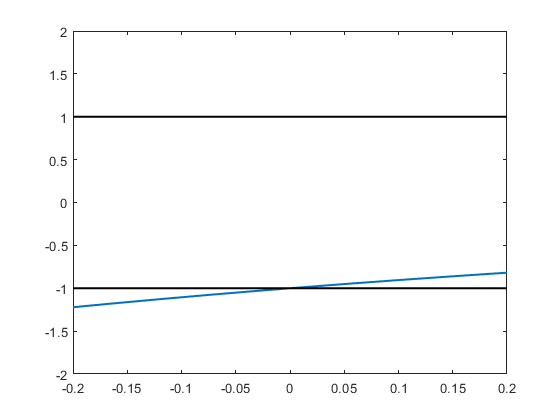

x = [-0.2:0.01:0.2]; y = dg(x); oneline = ones(size(x));
plot(x,y,x,oneline,'k',x,-oneline,'k','LineWidth',1.5); ylim([-2 2]);

array2table([x' y'], "VariableNames", {'x', 'y'})

ans = 41×2 table
      x              y        
    _____    _________________

     -0.2    -1.22140275816017
    -0.19    -1.20924959765725
    -0.18    -1.19721736312181
    -0.17    -1.18530485132037
    -0.16    -1.17351087099181
    -0.15    -1.16183424272828
    -0.14    -1.15027379885723
    -0.13    -1.13882838332462
    -0.12    -1.12749685157938
    -0.11    -1.11627807045887
     -0.1    -1.10517091807565
    -0.09    -1.09417428370521
    -0.08    -1.08328706767496
    -0.07    -1.07250818125422
    -0.06    -1.06183654654536
    -0.05    -1.05127109637602


Podemos, tanto grafica como numericamente, ver que a **exactamente en 0, la funcion se evalua en -1**, ya partir de este punto, dado que es una funcion derivada es inversa exponencial, tienen una **asintota horizontal en y = 0** y nunca llegara a sobrepasar la linea y = 1. Por lo tanto podemos asegurar que la funcion convergera **para todo x0 > 0**.

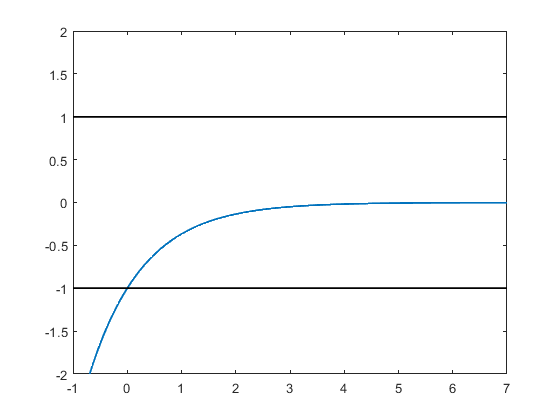

x = [-1:0.01:7]; oneline = ones(size(x));
plot(x,dg(x),x,oneline,'k',x,-oneline,'k','LineWidth',1.5); ylim([-2 2]);

Calculo de iteraciones:

[alpha, it] = itera(g,x0,10^9,eps,eps,false)

alpha =    0.567143290409784


it =     62


Si utilizamos el metodo de iteracion simple, obtenemos el resultado con tolerancia  = eps, en **62 iteraciones**.

# PRACTICA 18

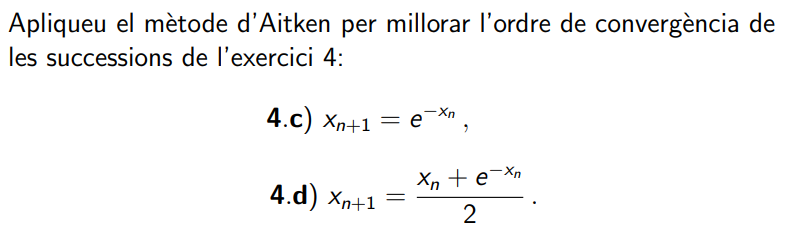

g1 = @(x) exp(-x);
g2 = @(x) (x + exp(-x))/2;

T1 = aitken(g1,0.5,30,"mat");
T2 = aitken(g1,0.5,30,"mat");

array2table([T1 T2(:,2:end)],"VariableNames",{'n','g1','g1_Aitken','g2','g2_Aitken'})

ans = 31×5 table
    n            g1                g1_Aitken               g2                g2_Aitken    
    __    _________________    _________________    _________________    _________________

     0                  0.5                  NaN                  0.5                  NaN
     1    0.606530659712633                  NaN    0.606530659712633                  NaN
     2    0.545239211892605     0.56762387641092    0.545239211892605     0.56762387641092
     3    0.579703094878068     0.56729898932651    0.579703094878068     0.56729898932651
     4    0.560064627938902    0.567193142398219    0.560064627938902    0.567193142398219
     5    0.571172148977215    0.567159364489465    0.571172148977215    0.567159364489465
     6    0.564862946980323    0.567148453258233    0.564862946980323    0.567148453

## Funciones

function [alpha, it] = itera(g,x0,maxiter,tolf,tolx, table)

    if (table)
        T = zeros(maxiter, 4);  % reservo el espacio maximo
    end      
    
    x = x0;
    for it = 1:maxiter
        
        x_next = g(x);
        tolx_aux = abs(x_next - x);
        tolf_aux = abs(g(x_next) - x_next);
        
        if (table)
            T(it,:) = [it, x_next, tolx_aux, tolf_aux];
        end
        
        if (tolx_aux < tolx && tolf_aux < tolf) % test de parada
            break; 
        end
        x = x_next;
        
    end
    alpha = x;
    
    if (it == maxiter)
        disp("Numero maximo de iteraciones alcanzado.");
    end
    
    if (table)
        T = T(1:it,:);          % libero el espacio no usado
        array2table(T, 'VariableNames', {'it', 'x_next', 'tolx_aux', 'tolf_aux'})
    end

end

% -------------------------------------------------------------------------------------------------------

function T = aitken(g, x, n, mode)

    x0 = x;
    x1 = g(x0);
    
    T = [0 x0 NaN; 1 x1 NaN];
    
    for it=2:n
        
        x2 = g(x1);
        x2_prime = (x2*x0 - x1*x1)/(x2 - 2*x1 + x0); 
        
        T = [T; it x2 x2_prime];
        
        x0 = x1;
        x1 = x2;
        
    end
    
    if (mode == "table")
        T = array2table(T,"VariableNames",{'it', 'x2', 'x2_prime'});
    end

end